%%Segmentering af sudukoplade felter
clear; close all; clc
x = 'suduko_mellem2.png' %Zoom PDF 132%

x = 'suduko_mellem2.png'

sudukoBW=imread(x);
imfinfo 'suduko_mellem2.png'

ans = struct with fields:
                  Filename: 'C:\Users\jacob\Documents\EDE - AU Herning\5. EDE EH21-5\ADSB\ADSB_projekt\statisk billede test\suduko_mellem2.png'
               FileModDate: '05-Nov-2021 10:18:20'
                  FileSize: 18743
                    Format: 'png'
             FormatVersion: []
                     Width: 475
                    Height: 475
                  BitDepth: 24
                 ColorType: 'truecolor'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: []
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'alpha'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: 'perceptual'
            Chromaticities: [0.3127 0.329 0.64 0.33 0.3 0.6 0.15 0.06]
                     Gamma: 0.45455
               XResolution: 3779
               YResolution: 3779
            ResolutionUnit: 'meter'
                   XOffset: []
              

imfinfo 'suduko_lille.png'

ans = struct with fields:
                  Filename: 'C:\Users\jacob\Documents\EDE - AU Herning\5. EDE EH21-5\ADSB\ADSB_projekt\statisk billede test\suduko_lille.png'
               FileModDate: '05-Nov-2021 10:18:20'
                  FileSize: 20078
                    Format: 'png'
             FormatVersion: []
                     Width: 475
                    Height: 475
                  BitDepth: 24
                 ColorType: 'truecolor'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: []
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: 'perceptual'
            Chromaticities: [0.3127 0.329 0.64 0.33 0.3 0.6 0.15 0.06]
                     Gamma: 0.45455
               XResolution: 3779
               YResolution: 3779
            ResolutionUnit: 'meter'
                   XOffset: []
                 

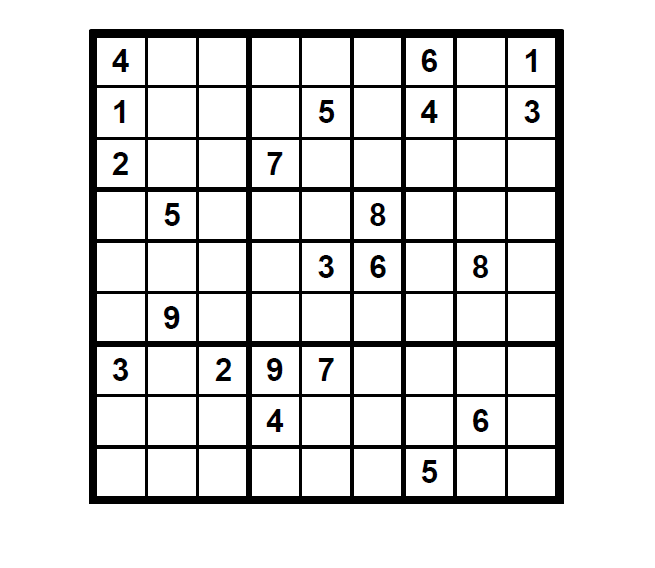

%sudukoBW=imresize(sudukoBW,1.5);
figure
imshow(sudukoBW)

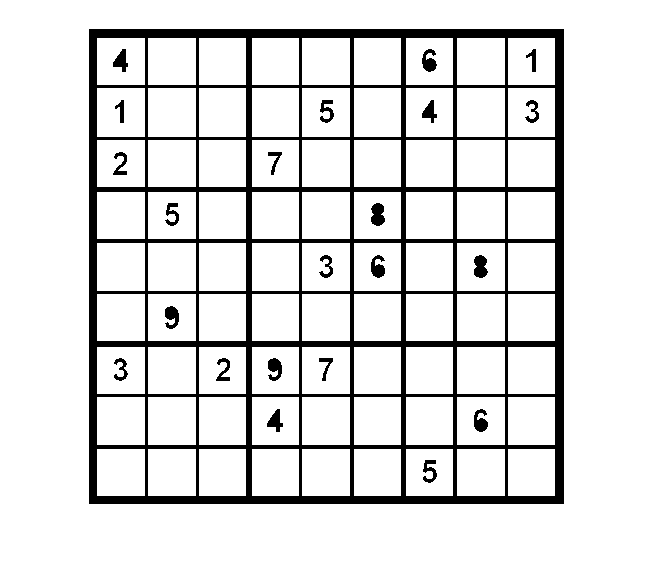

   data = sudukoBW;
    imChange1 = rgb2gray(data);
    %imChange2 = medfilt2(imChange1, [1 1]);
    imChange3 = imbinarize(imChange1,0.18); %0.18 normalt (0.07 ved grøn)  (im2bw)
    imChange4 = bwareaopen(imChange3,200); %300
    bw = bwlabel(imChange4, 8);
    felt_data = regionprops(bw, 'BoundingBox', 'Centroid');
    
    figure
    imshow(bw);

    imagesc(data);
    
    hold on
    
    pos_data = []


pos_data =

     []



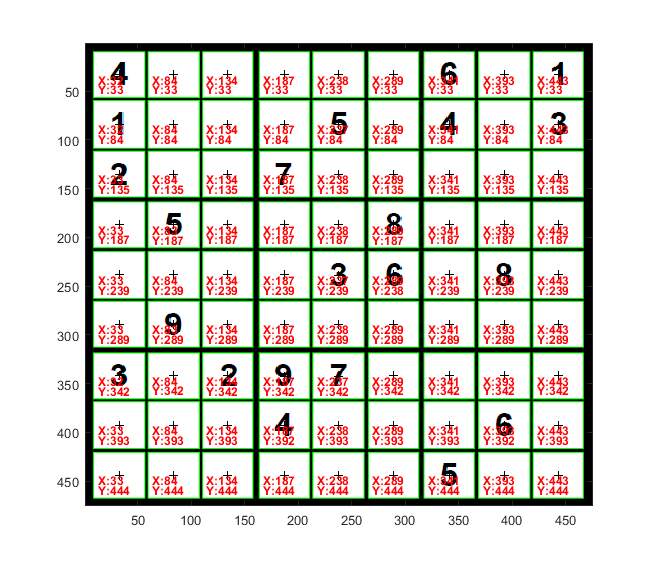

    for object = 1:length(felt_data)
        bb = felt_data(object).BoundingBox;
        bc = felt_data(object).Centroid;
        
        pos_data = [bc];
        rectangle('Position',bb,'EdgeColor','g','LineWidth',0.8)
        plot(bc(1),bc(2), '-black+')
       
        textX=text(bc(1)-20,bc(2)+5, strcat('X:', num2str(round(bc(1)))));
        textY=text(bc(1)-20,bc(2)+15, strcat('Y:', num2str(round(bc(2)))));
        set(textX, 'FontName', 'Arial', 'FontWeight', 'bold', 'FontSize', 9, 'Color', 'red');
        set(textY, 'FontName', 'Arial', 'FontWeight', 'bold', 'FontSize', 9, 'Color', 'red');
    end
    hold off

 pos_data

pos_data =    443   444


 format short G
 felt_data

felt_data = 81×1 struct array with fields:
    Centroid
    BoundingBox


x_center =[];
y_center =[];
 for i = 0:size(felt_data)-1
     find_x=felt_data(1+i).Centroid(1);
     x_center = [x_center,find_x];
     find_y=felt_data(1+i).Centroid(2);
     y_center = [y_center,find_y];
 end
 
 x_center

x_center =        32.463       32.485       32.511         32.5         32.5         32.5       32.478         32.5         32.5         83.5         83.5         83.5       83.474         83.5       83.499         83.5         83.5         83.5          134          134          134          134          134          134        133.9          134          134          187          187       187.04          187          187          187       187.05       186.99          187        237.5       237.43        237.5        237.5       237.44        237.5        237.5        237.5        237.5          289          289          289       288.96       288.97


y_center

y_center =        33.049       84.078       134.93          187        238.5          289       342.06        392.5          444           33           84          135       187.11        238.5        289.1          342        392.5          444           33           84          135          187        238.5          289       342.01        392.5          444           33           84       135.18          187        238.5          289       342.21       392.48          444           33       84.129          135          187       238.52          289       342.23        392.5          444           33           84          135        187.1       238.44



%koordinater på boksene - X og Y på venstre top hjørne og højre nedre
%hjørne 

x_box_topLeft=[];
y_box_topLeft=[];

x_box_botRight=[];
y_box_botRight=[];
for i = 0:size(felt_data)-1
     find_x1=felt_data(1+i).BoundingBox(1);
     x_box_topLeft = [x_box_topLeft,find_x1];
     
     find_y1=felt_data(1+i).BoundingBox(2);
     y_box_topLeft = [y_box_topLeft,find_y1];
     
     
     
     find_x2=felt_data(1+i).BoundingBox(3);
     x_box_botRight = [x_box_botRight,(find_x2+find_x1)];
     
     find_y2=felt_data(1+i).BoundingBox(4);
     y_box_botRight = [y_box_botRight,(find_y2+find_y1)]; 
     
     
 end
 x_box_topLeft

x_box_topLeft =           8.5          8.5          8.5          8.5          8.5          8.5          8.5          8.5          8.5         59.5         59.5         59.5         59.5         59.5         59.5         59.5         59.5         59.5        110.5        110.5        110.5        110.5        110.5        110.5        110.5        110.5        110.5        163.5        163.5        163.5        163.5        163.5        163.5        163.5        163.5        163.5        213.5        213.5        213.5        213.5        213.5        213.5        213.5        213.5        213.5        265.5        265.5        265.5        265.5        265.5


 
 y_box_topLeft

y_box_topLeft =           9.5         59.5        111.5        163.5        214.5        265.5        318.5        368.5        420.5          9.5         59.5        111.5        163.5        214.5        265.5        318.5        368.5        420.5          9.5         59.5        111.5        163.5        214.5        265.5        318.5        368.5        420.5          9.5         59.5        111.5        163.5        214.5        265.5        318.5        368.5        420.5          9.5         59.5        111.5        163.5        214.5        265.5        318.5        368.5        420.5          9.5         59.5        111.5        163.5        214.5


 
 x_box_botRight

x_box_botRight =          56.5         56.5         56.5         56.5         56.5         56.5         56.5         56.5         56.5        107.5        107.5        107.5        107.5        107.5        107.5        107.5        107.5        107.5        157.5        157.5        157.5        157.5        157.5        157.5        157.5        157.5        157.5        210.5        210.5        210.5        210.5        210.5        210.5        210.5        210.5        210.5        261.5        261.5        261.5        261.5        261.5        261.5        261.5        261.5        261.5        312.5        312.5        312.5        312.5        312.5


y_box_botRight

y_box_botRight =          56.5        108.5        158.5        210.5        262.5        312.5        365.5        416.5        467.5         56.5        108.5        158.5        210.5        262.5        312.5        365.5        416.5        467.5         56.5        108.5        158.5        210.5        262.5        312.5        365.5        416.5        467.5         56.5        108.5        158.5        210.5        262.5        312.5        365.5        416.5        467.5         56.5        108.5        158.5        210.5        262.5        312.5        365.5        416.5        467.5         56.5        108.5        158.5        210.5        262.5


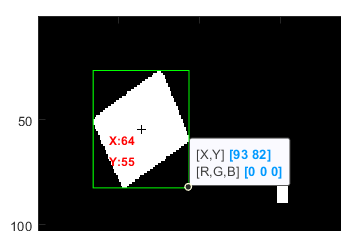

34.5+59 = modsatte hjørne kordinat X

26.5+56 = modsatte hjørnekordinat Y

  
    %opdater figur ved hvert loop:
    %drawnow;

% Her laver vi vores korrelations profiler :)
boundaries=bwboundaries(imChange4);

Image = {}


Image =

  0×0 empty cell array



for i = 1:81
    [xmin, ymin]=min(boundaries{i,1}); % for the first character you will have to run this for the total number of boxes drawn
    [xmax, ymax]=max(boundaries{i,1});
    Image{end+1,1}=imChange1(xmin(1,1):xmax(1,1),xmin(1,2):xmax(1,2)); % This the image which has the first character
end
Image

Image = 81×1 cell array
    {47×48 uint8}
    {49×48 uint8}
    {47×48 uint8}
    {47×48 uint8}
    {48×48 uint8}
    {47×48 uint8}
    {47×48 uint8}
    {48×48 uint8}
    {47×48 uint8}
    {47×48 uint8}
    {49×48 uint8}
    {47×48 uint8}
    {47×48 uint8}
    {48×48 uint8}
    {47×48 uint8}
    {47×48 uint8}


grid= correlationImage(Image);
grid

grid =      1     0     0     0     0     0     6     0     4
     4     0     0     0     5     0     1     0     3
     2     0     0     7     0     0     0     0     0
     0     5     0     0     0     8     0     0     0
     0     0     0     0     3     6     0     8     0
     0     9     0     0     0     0     0     0     0
     3     0     2     9     7     0     0     0     0
     0     0     0     1     0     0     0     6     0
     0     0     0     0     0     0     5     0     0


% grid_solved = sudokuSolver(grid)    
S = zeros(9,9);
grid_solved = sudoku(grid,S);
grid_solved(:,:,2)

ans =      1     7     5     3     8     9     6     2     4
     4     8     9     6     5     2     1     7     3
     2     3     6     7     4     1     8     9     5
     6     5     1     2     9     8     3     4     7
     7     2     4     5     3     6     9     8     1
     8     9     3     4     1     7     2     5     6
     3     6     2     9     7     5     4     1     8
     5     4     8     1     2     3     7     6     9
     9     1     7     8     6     4     5     3     2


clear; close all;
x = 'test_philip_new2.png' %Zoom PDF 132%

x = 'test_philip_new2.png'

sudukoBW=imread(x);
imfinfo 'test_philip_new2.png'

ans = struct with fields:
                  Filename: 'C:\Users\jacob\Documents\EDE - AU Herning\5. EDE EH21-5\ADSB\ADSB_projekt\statisk billede test\test_philip_new2.png'
               FileModDate: '05-Nov-2021 10:18:20'
                  FileSize: 2207
                    Format: 'png'
             FormatVersion: []
                     Width: 120
                    Height: 120
                  BitDepth: 24
                 ColorType: 'truecolor'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: []
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: 'perceptual'
            Chromaticities: [0.3127 0.329 0.64 0.33 0.3 0.6 0.15 0.06]
                     Gamma: 0.45455
               XResolution: 3779
               YResolution: 3779
            ResolutionUnit: 'meter'
                   XOffset: []
              

newSizes = size(sudukoBW);
newWidth = newSizes(1);
newHeight = newSizes(2);
originalWidth = 475;
originalHeight = 475;

interPolationValue = originalWidth/newWidth

interPolationValue =        3.9583


sudukoBW = imsharpen(sudukoBW,'Radius',0.1,'Amount',1);
sudukoBW = imresize(sudukoBW,interPolationValue);
size(sudukoBW)

ans =    475   475     3


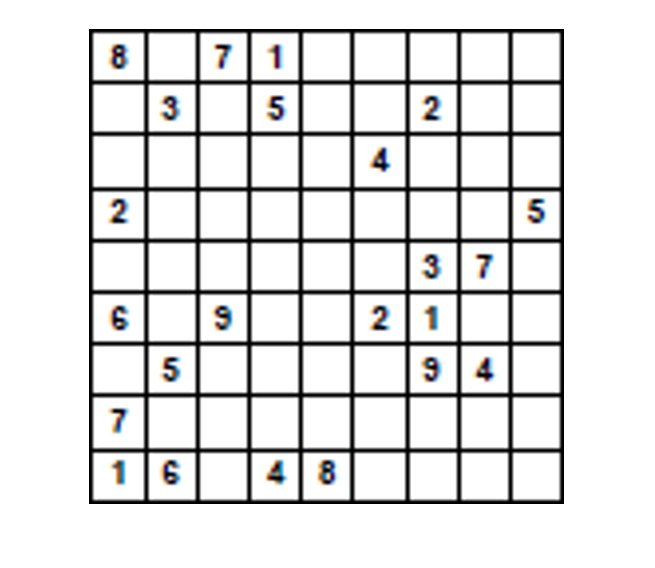

imshow(sudukoBW)

figure

imshow(sudukoBW)

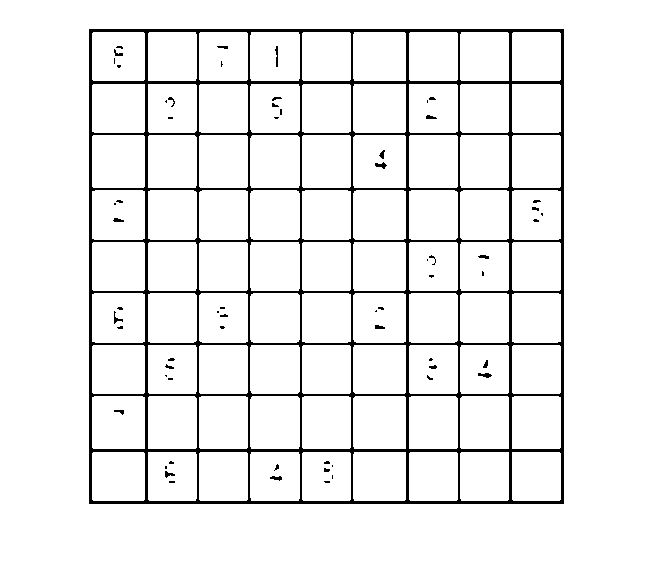


   data = sudukoBW;
    imChange1 = rgb2gray(data);
    %imChange2 = medfilt2(imChange1, [1 1]);
    imChange3 = imbinarize(imChange1,0.18); %0.18 normalt (0.07 ved grøn)  (im2bw)
    imChange4 = bwareaopen(imChange3,200); %300
    bw = bwlabel(imChange4, 4);
    felt_data = regionprops(bw, 'BoundingBox', 'Centroid');
    
    figure
    imshow(bw);

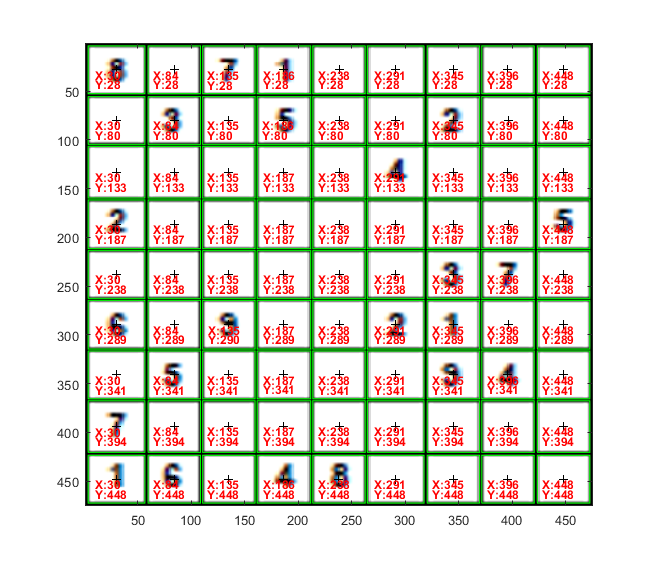

    imagesc(data);
    
    hold on
    
    pos_data = [];
    for object = 1:length(felt_data)
        bb = felt_data(object).BoundingBox;
        bc = felt_data(object).Centroid;
        
        pos_data = [bc];
        rectangle('Position',bb,'EdgeColor','g','LineWidth',0.8)
        plot(bc(1),bc(2), '-black+')
       
        textX=text(bc(1)-20,bc(2)+5, strcat('X:', num2str(round(bc(1)))));
        textY=text(bc(1)-20,bc(2)+15, strcat('Y:', num2str(round(bc(2)))));
        set(textX, 'FontName', 'Arial', 'FontWeight', 'bold', 'FontSize', 9, 'Color', 'red');
        set(textY, 'FontName', 'Arial', 'FontWeight', 'bold', 'FontSize', 9, 'Color', 'red');
    end
    hold off

 pos_data

pos_data =        447.99       447.99


 format short G
 felt_data

felt_data = 81×1 struct array with fields:
    Centroid
    BoundingBox


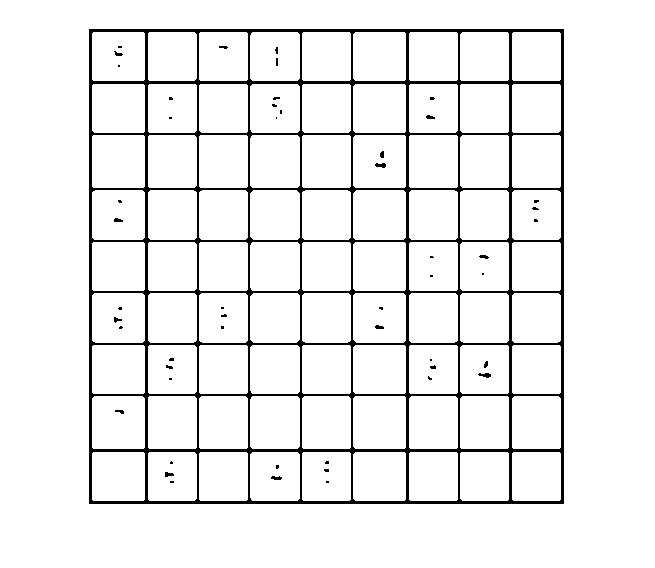

% Her laver vi vores korrelations profiler :)
h = fspecial('disk',2);
imChange4 = imfilter(imChange4,h);
imshow(imChange4)

boundaries=bwboundaries(imChange4);

Image = {}


Image =

  0×0 empty cell array



for i = 1:81
    [xmin, ymin]=min(boundaries{i,1}); % for the first character you will have to run this for the total number of boxes drawn
    [xmax, ymax]=max(boundaries{i,1});
    Image{end+1,1}=imChange1(xmin(1,1):xmax(1,1),xmin(1,2):xmax(1,2)); % This the image which has the first character
end
Image

Image = 81×1 cell array
    {49×53 uint8}
    {49×53 uint8}
    {53×53 uint8}
    {50×53 uint8}
    {49×53 uint8}
    {50×53 uint8}
    {49×53 uint8}
    {53×53 uint8}
    {49×53 uint8}
    {49×49 uint8}
    {49×49 uint8}
    {53×49 uint8}
    {50×49 uint8}
    {49×49 uint8}
    {50×49 uint8}
    {49×49 uint8}


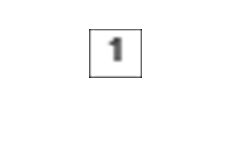

imshow(Image{9,1})

grid = correlationImage(Image);

grid %Så 1 & 4 og 3 og 8 giver forkert %

grid =      8     0     7     4     0     0     0     0     0
     0     8     0     5     0     0     2     0     0
     0     0     0     0     0     4     0     0     0
     2     0     0     0     0     0     0     0     5
     0     0     0     0     0     0     3     7     0
     6     0     9     0     0     2     4     0     0
     0     5     0     0     0     0     3     4     0
     2     0     0     0     0     0     0     0     0
     9     6     0     4     8     0     0     0     0


% grid_solved = sudokuSolver(grid)    
S = zeros(9,9);
grid_solved = sudoku(grid,S);
grid_solved

grid_solved =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0


%for loop der sætter alle grid værdierne ind som overlay på en tom
%sudukoplade. 
